# RVC toolbox: ikine

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 

qSolve = Robot_ABB.ikine(Target,[0 0 0 0 0 0],[1 1 1 1 1 1]); 	%inverse kinematics using iterative numerical method


q1 = qSolve(1)*(180/pi)

q1 = 1.1252e+05

q2 = qSolve(2)*(180/pi)

q2 = -110.8511

q3 = qSolve(3)*(180/pi)

q3 = 27.4054

q4 = qSolve(4)*(180/pi)

q4 = -2.5674e+05

q5 = qSolve(5)*(180/pi)

q5 = 4.0833e+04

q6 = qSolve(6)*(180/pi)

q6 = -42.1526

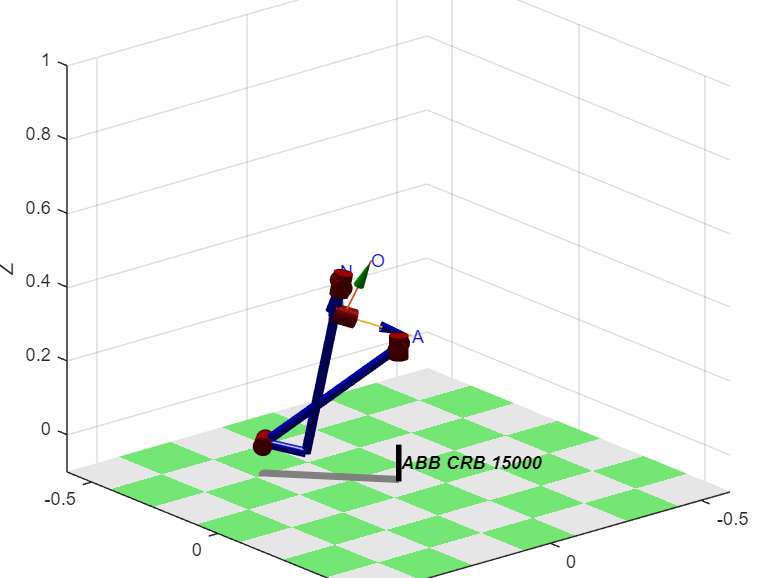

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

Robot_ABB.fkine([q1 q2 q3 q4 q5 q6])

ans =    -0.5743   -0.1259   -0.8089    0.0907
   -0.7644    0.4363    0.4748   -0.1106
    0.2931    0.8910   -0.3468    0.3397
         0         0         0    1.0000
